# Laboratorio di Automatica (prova del 12 Giugno 2018)

Riccardo Antonello ([riccardo.antonello@unipd.it](mail:riccardo.antonello@unipd.it)) and Angelo Cenedese ([angelo.cenedese@unipd.it](mail:angelo.cenedese@unipd.it)) 

June 12, 2018

Dept. of Information Engineering, University of Padova

## Esercizio 3

Sia 


$$P(s)\,=\, \frac{Y(s)}{U(s)} \,=\, \frac{k_m}{s(T_m s  + 1)}
\qquad\quad\text{con}\qquad\quad
k_m\,=\,5.2\,,\qquad T_m \,=\,0.03$$


la funzione di trasferimento di un motore elettrico in corrente continua, da ingresso in tensione $u$ $[V]$ ad uscita in posizione $y$ $[\mathrm{rad}]$. Si supponga di controllare la posizione del motore mediante il sistema di controllo a dati campionati riportato in Fig. 3.

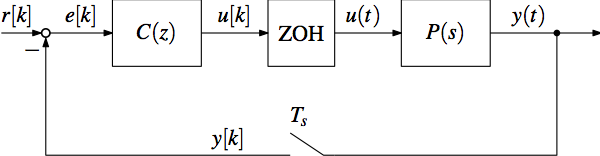

**Figura 3**: Sistema di controllo a *dati campionati* con retroazione unitaria dall'uscita.

Si assuma che:

1)  il controllore digitale con funzione di trasferimento $C(z)$ sia ottenuto per discretizzazione, con il metodo di *Eulero in avanti (forward Euler method)*, del seguente controllore PID a tempo continuo


$$C(s) \,=\, \frac{U(s)}{E(s)} \,=\; 
K_P \,+\, \frac{K_I}{s} \,+\, \frac{K_D\,s}{T_L\,s\,+\,1} $$


con 


$$K_P \,=\, 8.7\,,\qquad
K_I \,=\, 120.0\,,\qquad
K_D \,=\, 0.16\,,\qquad
T_L \,=\, 0.0053$$


dove l'errore di inseguimento $e[k]$ (ingresso del controllore) si assume espresso in $[\mathrm{rad}]$.

Per la discretizzazione, si consideri un periodo di campionamento pari a $T_s = 5\,ms$. Si ricorda che la funzione di trasferimento discretizzata si ottiene a partire dalla corrispondente funzione di trasferimento a tempo continuo mediante la sostituzione formale


$$s \,=\, \frac{z-1}{T_s}$$


2)  l'uscita $u[k]$ del controllore saturi per valori eccedenti i limiti di $\pm 10\,V$.

3)  la misura di posizione $y[k]$ sia fornita da un encoder con risoluzione pari a $500\,\mathrm{ppr}$ (*ppr = pulses per rotation*, ovvero impulsi per giro).

Si svolgano i seguenti punti:

1)  Realizzare uno schema Simulink del sistema di controllo a dati campionati di Fig. 3.

*Nota*: per simulare sia il campionatore che lo Zero-Order Holder (ZOH), si faccia ricorso al blocco *Discrete *$\rightarrow$* Zero-Order Hold* della libreria di blocchi del Simulink.

*Soluzione.*

%   conversion gains
rad2deg = 180/pi;
deg2rad = pi/180;

%   plant model (in: driver voltage [V]; out: load position [rad])
s = tf('s');
sysP = 5.2/((0.03*s+1)*s);
[numP, denP] = tfdata(sysP, 'v');

%   sampling time
Ts = 0.005;

%   controller params
Kp = 8.7;
Ki = 120.0;
Kd = 0.16;
TL = 0.0053;

%   encoder parameters
enc_ppr = 500;                  %  pulses per rotation
enc_pulse2deg = 360/enc_ppr;    %  quantization interval [deg/pulse]

%   open model
open('ex3_sim1');

2)  Simulare la risposta del sistema di controllo a dati campionati con un riferimento di posizione a gradino di ampiezza pari a $A = 360\,\mathrm{deg}$, applicato in $t_0 = 0.1\,s$ (si faccia attenzione ad usare le stesse unità di misura per il segnale di riferimento $r$ e l'uscita in posizione $y$).

*Soluzione.*

%   step reference 
Ar = 360;
t0r = 0.1;

%    set simulation params
set_param('ex3_sim1', 'SolverType', 'Variable-step', ...
    'Solver', 'ode45', 'MaxStep', '0.001', 'StopTime','2');

%   run simulation
sim('ex3_sim1');

3)  Con riferimento alla simulazione eseguita al punto 2, mostrare in una figura Matlab gli andamenti dei seguenti segnali:

- *plot 1:* uscita $y[k]$ e riferimento $r[k]$, entrambi espressi in $[deg]$ (gradi).

- *plot 2*: errore di inseguimento $e[k]$, espresso in $[deg]$.

- *plot 3*: tensione $u[k]$, espressa in $[V]$.

Valutare inoltre l'overshoot percentuale della risposta al gradino.

*Soluzione.*

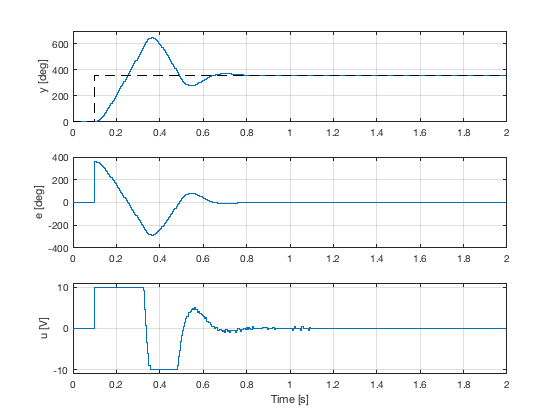

%   extract signals
t = simres.time;
y = simres.signals(1).values(:,1);
r = simres.signals(1).values(:,2);
e = simres.signals(2).values(:,1);
u = simres.signals(3).values(:,1);

%   plot results
figure;
subplot(3,1,1);
stairs(t, y);
hold on;
stairs(t, r, 'k--');
ylabel('y [deg]');
ylim([0, 700]);
grid on;

subplot(3,1,2);
stairs(t, e);
ylabel('e [deg]');
ylim([-400, 400]);
grid on;

subplot(3,1,3);
stairs(t, u);
ylabel('u [V]');
xlabel('Time [s]');
% ylim([-11,11]);
grid on;


%    overshoot
info = stepinfo(y, t);
info.Overshoot

ans = 79.8000

4)  Introdurre uno schema di desaturazione dell'azione integrale (*integrator anti-windup*) nel modello Simulink del sistema di controllo preparato al punto 1, analogamente a quanto visto a lezione. Si scelga una costante di desaturazione dell'azione integrale pari a $K_{AWU} = 25$.

*Soluzione*.

%   anti-windup gain
kAWU = 25;

%   open model
open('ex3_sim2');

5)  Simulare la risposta del sistema di controllo predisposto al punto 4, con lo stesso segnale di riferimento utilizzato nella simulazione del punto 2. Successivamente, mostrare i risultati della simulazione in una figura Matlab analoga a quella prodotta nel punto 3. Valutare inoltre l'overshoot percentuale della risposta al gradino.

*Soluzione.*

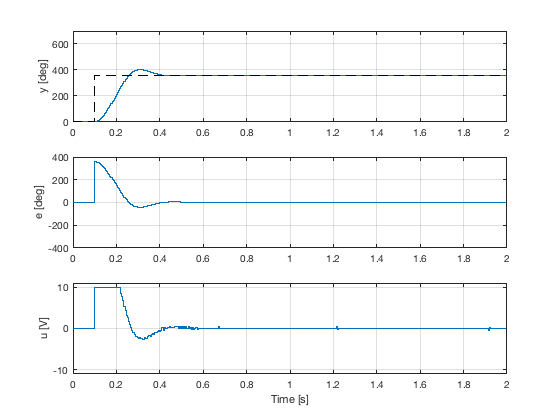

%    set simulation params
set_param('ex3_sim2', 'SolverType', 'Variable-step', ...
    'Solver', 'ode45', 'MaxStep', '0.001', 'StopTime','2');

%   run simulation
sim('ex3_sim2');

%   extract signals
t = simres.time;
y = simres.signals(1).values(:,1);
r = simres.signals(1).values(:,2);
e = simres.signals(2).values(:,1);
u = simres.signals(3).values(:,1);

%   plot results
figure;
subplot(3,1,1);
stairs(t, y);
hold on;
stairs(t, r, 'k--');
ylabel('y [deg]');
ylim([0, 700]);
grid on;

subplot(3,1,2);
stairs(t, e);
ylabel('e [deg]');
ylim([-400, 400]);
grid on;

subplot(3,1,3);
stairs(t, u);
ylabel('u [V]');
xlabel('Time [s]');
ylim([-11,11]);
grid on;


%    overshoot
info = stepinfo(y, t);
info.Overshoot

ans = 11.6000